# Sessio 8

**Yaiza Cano, Narcís Terrado**

## Introducció

Durant aquesta pràctica consolidarem els coneixement sobre segmentació i filtrat apresos en sessions anterios.

## Segmentació per Watershed

En aquesta primera part de la pràctica, repassarem com es segmentava una imatge mitjançant *watershed.*

Per fer això, carregarem la imatge *cornea.tif *i intentarem aplicar-li el *watershed* amb el seu *gradient*.

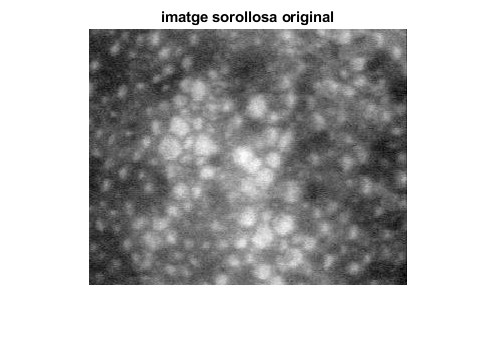

%obrim la imatge
orig = imread('cornea.tif');
figure, imshow(orig); title('imatge sorollosa original')

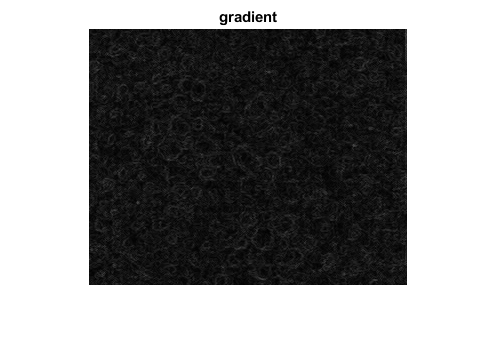


%calculem el gradient
ee = strel('disk',1);
grad = imsubtract(imdilate(orig,ee), imerode(orig,ee));
figure, imshow(grad), title('gradient');

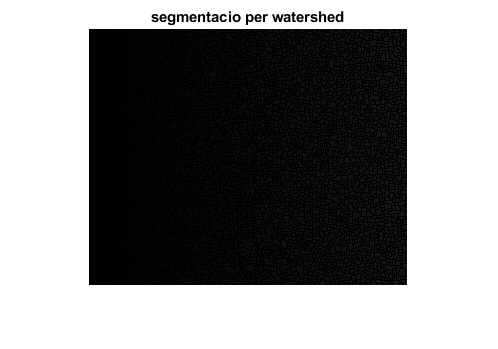


%segmentem la imatge amb watershed
segm = watershed(grad);
figure, imshow(segm), title('segmentacio per watershed')

Com vam veure a la sessió anterior, no podem segmentar la imatge utilitzant el gradient, necessitem treballar markers. Usarem els màxims regionals com a markers de les cèlules.

Però abans d'això hem de filtrar la imatge ja que aquesta és molt sorollosa.

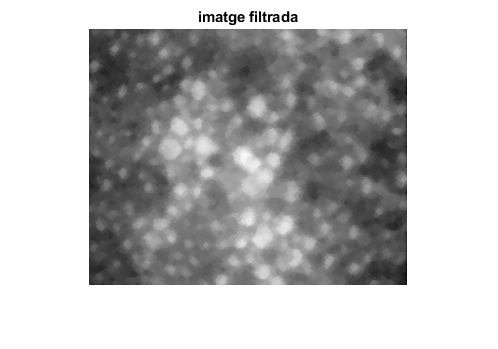

ee = strel('disk', 2);
filt = imopen(imclose(orig,ee),ee); 
figure, imshow(filt); title('imatge filtrada')

A continuació extreurem els màxims regionals i els utilitzarem com a markers pel watershed fent un overlay en color. 

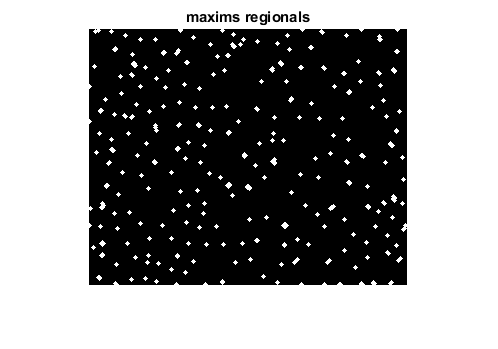

rm = imregionalmax(filt);
figure, imshow(rm), title('maxims regionals')

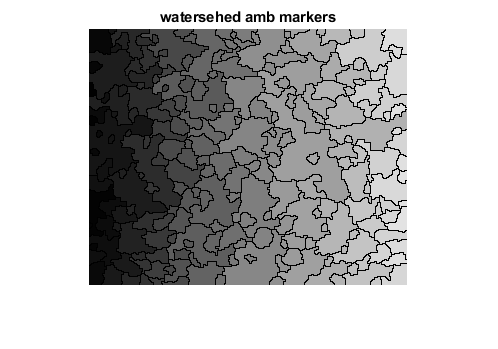


segm=watershed(imimposemin(grad,rm));
figure,imshow(segm),title('watersehed amb markers')

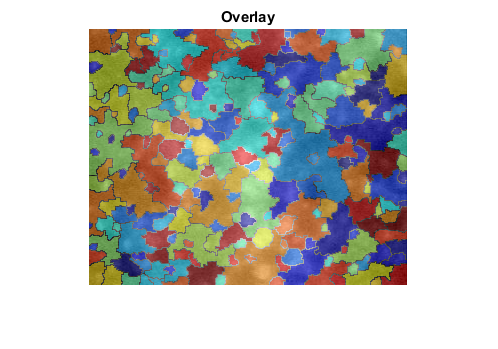


ol = labeloverlay(orig, segm);
figure, imshow(ol), title("Overlay")

Com podem observar, hi ha moltes cèlules que es confonen amb el fons, això és degut a hem utilitzat *només* els màxims regionals com a marker i no estem tenint en compte el fons de la imatge.

Així doncs, el següent pas és trobar un marker pel fons. Aquest, l'obtindrem de la imatge negada i utilitzarem com a marker els mateixos màxims d'abans.

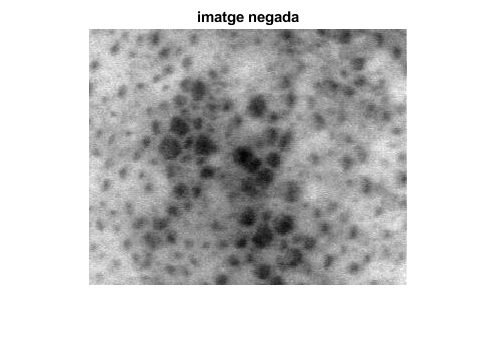

Norig=imcomplement(orig);
figure,imshow(Norig),title('imatge negada')

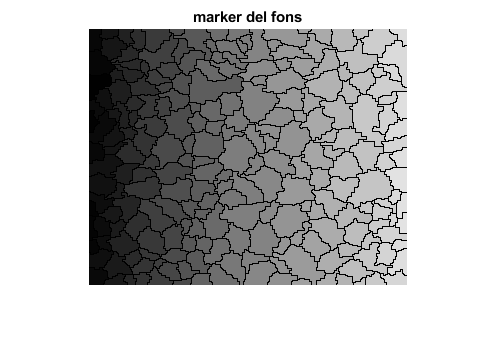

fons=watershed(imimposemin(Norig,rm));
figure,imshow(fons),title('marker del fons')

Computem la imatge de markers a partir de les cèlules i del fons i visualitzem el resultat amb un nou *overlay.*

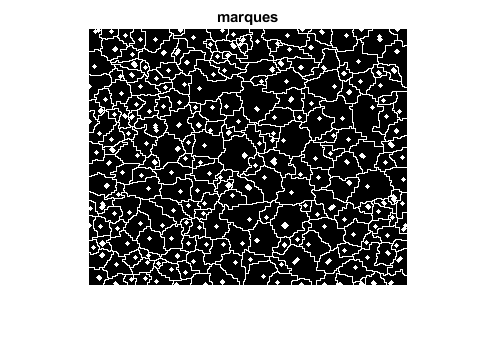

markers=~fons|rm;
figure,imshow(markers),title('marques')

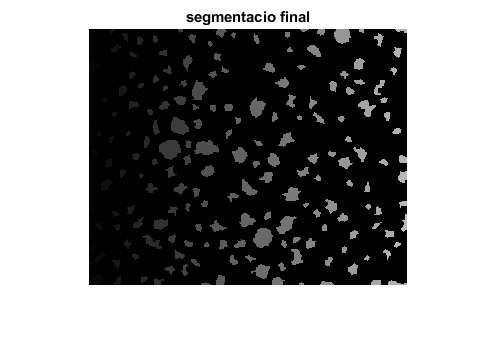


% fem el watershed amb les noves marques
segm=watershed(imimposemin(grad,markers));
figure,imshow(segm),title('segmentacio final')

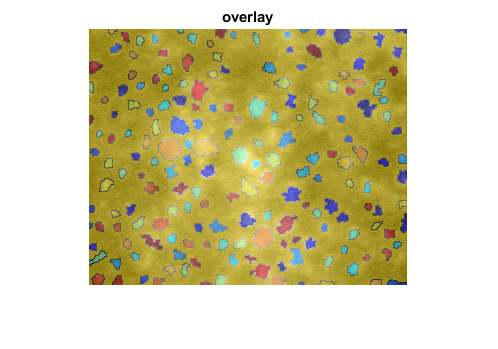


ol = labeloverlay(orig, segm);
figure, imshow(ol), title("overlay")

AQUESTA MERDA NO FUNCIONA.

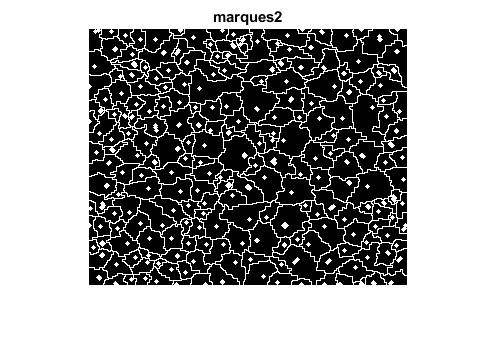

se = strel('disk', 1);
markers2 = imopen(markers, se);
markers2 = imerode(markers2, se);
markers2 = imreconstruct(markers2, markers);
figure,imshow(markers2),title('marques2')

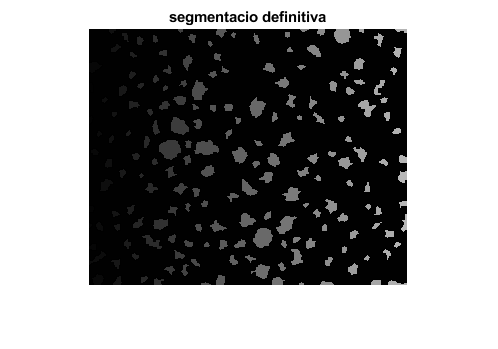


segm=watershed(imimposemin(grad,markers2));
figure,imshow(segm),title('segmentacio definitiva')

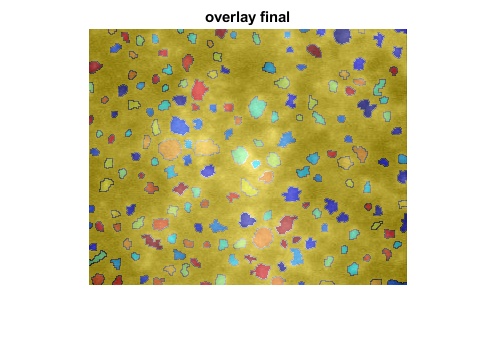


ol = labeloverlay(orig, segm);
figure, imshow(ol), title("overlay final")

## Segmentació per K-Means

Durant aquesta segona part de la pràctica, repassarem com es segmentava una imatge mitjançant *clustering.*

Per fer això, carregarem la imatge *peppers.png, *canviarem d'espai RGB a Hue-Sat i li aplicarem la funció predefinida de Matlab, *kmeans *amb els arguments *distance *i *cityblock* que calculen les medianes de cada cluster amb el sumatori de la diferencia en valor absolut de cada punt a la posició del cluster.

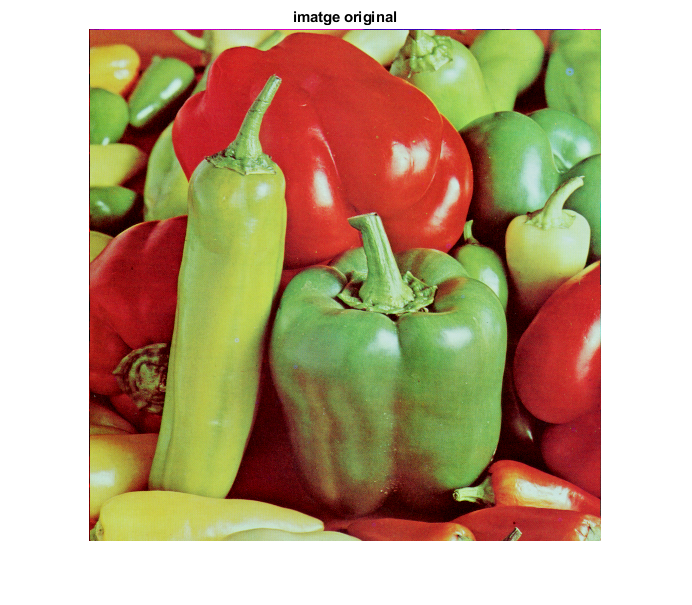

im = imread("peppers.png");
[MAXFILA, MAXCOL, chan]=size(im);
figure,imshow(im),title('imatge original')

hsv=rgb2hsv(im);
hs=hsv(:,:,1:2);
vect=reshape(hs,MAXFILA*MAXCOL,2); % feature vector. 2 features per píxel
Nclusters=3; %vermell, verd, i negre
[cluster_idx, cluster_center] = kmeans(vect,Nclusters,'distance','cityblock');

Refem la imatge segons el número de clusters.

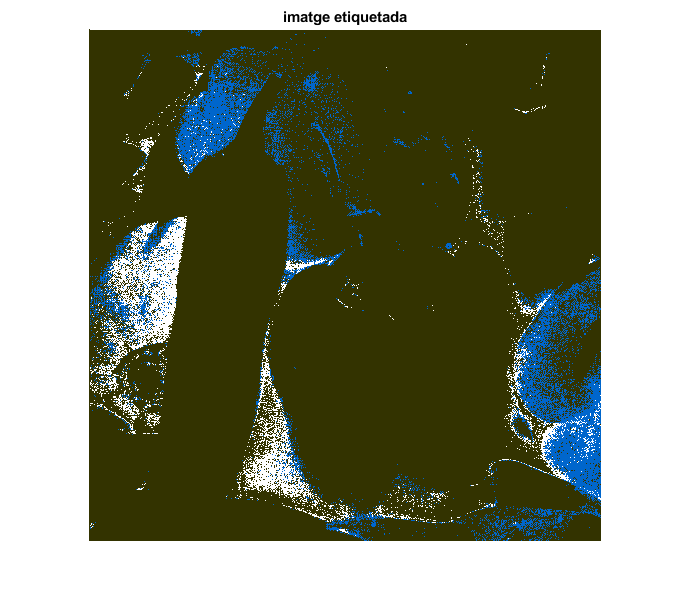

eti=reshape(cluster_idx,MAXFILA,MAXCOL);
figure,imshow(eti,[]),colormap(colorcube), title('imatge etiquetada')

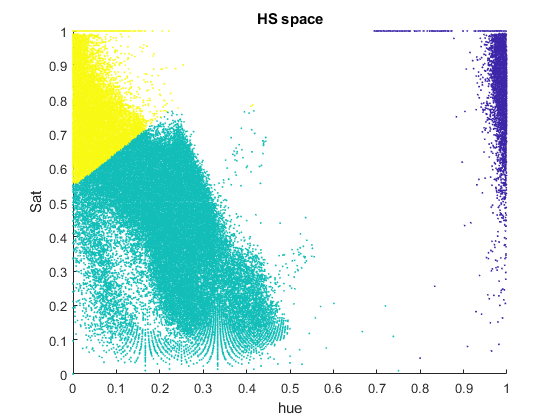

figure,scatter(vect(:,1),vect(:,2),1,cluster_idx);
xlabel('hue');ylabel('Sat')
title('HS space')

Com podem veure, la segmentació dels pebrots vermells és incorrecta, això és degut a que l'espai Hue és un angle, és a dir, conté característiques cícliques que la funció *kmeans* no sap interpretar.

Per aquest motiu, hem intentat dissenyar un *kmeans *que funcioni amb angles per obtenir millors resultats.

Per implemenntar el algorisme de K-Means el primer que fem és generar 3 punts aleatoris, que seràn els centroids inicials, són punts generats aleatòriament. Després per a cada punt de la imatge en l'espai HS, en calculem la distància a cada un dels centroids. Al ser angles, la distància es calcula tenint en compte que l'espai H és cíclic. Cada punt és assignat al centroid que estigui a una distància menor. Una vegada fet això amb tots els punts de la imatge, recalculem els centroids a partir de la mitja dels punts assignats a cada un d'ells. La mitja, al tractar-se de valors cíclics, també s'ha de calcular tractant els punts de H com a angles. Realitzem aquest procediment fins que els centroids canvien menys d'un llindar assignat per nosaltres.

c1 = cat(2, rand(1), rand(1));
c2 = cat(2, rand(1), rand(1));
c3 = cat(2, rand(1), rand(1));
cc1 = [0,0];
cc2 = [0,0];
cc3 = [0,0];
[row, col] = size(vect);
idx = zeros(row,1);
v1 = [];
v2 = [];
v3 = [];

while ( abs(cc1-c1) > 0.001 | abs(cc2-c2) > 0.001 | abs(cc3-c3) > 0.001)
    cc1 = c1;
    cc2 = c2;
    cc3 = c3;
    idx = zeros(row,1);
    v1 = [];
    v2 = [];
    v3 = [];
    for p = 1:row
        d1 = min(abs(vect(p, 1)-c1(1)), 1-abs(vect(p, 1)-c1(1))) / 0.5;
        d2 = abs(vect(p, 2)-c1(2));
        distc1 = sqrt(d1^2+d2^2);
        
        d1 = min(abs(vect(p, 1)-c2(1)), 1-abs(vect(p, 1)-c2(1))) / 0.5;
        d2 = abs(vect(p, 2)-c2(2));
        distc2 = sqrt(d1^2+d2^2);
        
        d1 = min(abs(vect(p, 1)-c3(1)), 1-abs(vect(p, 1)-c3(1))) / 0.5;
        d2 = abs(vect(p, 2)-c3(2));
        distc3 = sqrt(d1^2+d2^2);
        
        mindist = min([distc3, distc2, distc1]);
        if mindist == distc1
            idx(p) = 1;
            v1 = [v1; vect(p,:)];
        elseif mindist == distc2
            idx(p) = 2;
            v2 = [v2; vect(p,:)];
        else
            idx(p) = 3;
            v3 = [v3; vect(p,:)];
        end
    end
    c1 = cat(2, getmeanh(v1(:,1)), mean(v1(:,2)));
    c2 = cat(2, getmeanh(v2(:,1)), mean(v2(:,2)));
    c3 = cat(2, getmeanh(v3(:,1)), mean(v3(:,2)));
end
a = 0;

eti=reshape(idx,MAXFILA,MAXCOL);
figure,imshow(eti,[]),colormap(colorcube), title('imatge etiquetada')
figure,scatter(vect(:,1),vect(:,2),1,idx);
xlabel('hue');ylabel('Sat')
title('HS space')

%%%%%%%%%%%

Aquest break + el següent són on he estat probant coses. 

He estat probant amb 180 i 0.5.

x = 0.0;
y = 0.0;
size = 57275;
for i = 1:size
    x = x + (cosd(v1(i,1)));
    y = y + (sind(v1(i,1)));
end
x = x/size;
y = y/size;
m = atan2(y,x);
m2 = mean(v1(:,1));

aux = [0,1];
ax = 0.0;
ay = 0.0;
for i = 1:2
    ax = ax + (cos(aux(i)) / 0.5 * pi);
    ay = ay + (sin(aux(i)) / 0.5 * pi);
end
ax = ax / 2;
ay = ay / 2;
am = atan2(ay,ax);
am2 = mean(aux);

r = sqrt(ay^2+ax^2);
axa = r * cos(am);
aya = r * sin(am);

